Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# 2D beam optics (Section 3.3.3, 3.3.5, 3.6.1, and 3.6.2)

Volker Ziemann, 211106, CC-BY-SA-4.0

In accelerators the elements, such as a magnet or the beam pipe between the magnets, follow one another and we represent them as lines in an array that describes this sequence. We describe drift space with a code=1 in the first column and thin quadrupoles by code=2. The second column contains the number the line is repeated internally, the third column displays the lenth of the element and the fourth column the strength. For a thin quadrupole the latter is specified as its focal length F. Summarizing

- First column: code, drift=1, quad=2

- Second column: repeat code for the element

- Third column: length of one segment

- Fourth column: strength of one segment, focal length for a thin quadrupole.

A simple FODO cell that starts  in the middle of the drift space before the defocusing quadrupole is thus defined in the following array, named `fodo,` where the focal length is defined as` F=2.1. `Just below the defionition of fodo we define the` beamline `as 20 copies of` fodo` stacked on top of each other.

global beamline sigma0 % needed for some functions.
F=2.1;   % focal length of the quadrupoles
fodo=[ 1,  5,  0.2,  0;    % 5* D(L/10)
	     2,  1,  0.0, -F;    % QD
	     1, 10,  0.2,  0;    % 10* D(L/10)  
	     2,  1,  0.0,  F;    % QF/2
       1,  5,  0.2,  0]   % 5* D(L/10)  
beamline=repmat(fodo,20,1)    % name must be 'beamline' 

Now calculate all the transfer matrices with the function `calcmat()` that is defined in the appendix

[Racc,spos,nmat,nlines]=calcmat(beamline);

Then we allocate memory to store the positions after each segment that we want to display later

data=zeros(1,nmat);   % allocate memory

and define the input state x0, which contains the starting position and angle

x0=[0.001;0];         % 1 mm offset at start

before mapping the input x0 to the state vector x at the end of each segment along the beam line

for k=1:nmat          
  x=Racc(:,:,k)*x0;

fodo =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0


  data(k)=x(1);       % store the position

beamline =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0


end

and annotate the axes

plot(spos,1e3*data,'k');   % 1e3 to convert to mm
xlabel('s [m]'); 
ylabel(' x [mm]'); 
title('Trajectory')
xlim([spos(1),spos(end)])

## Beta functions

Now we are ready to calculate the beta functions along the beamline. Let's first calculate the transfer matrices for a single fodo cell.

beamline=fodo;            % just a single FODO cell
[Racc,spos,nmat,nlines]=calcmat(beamline);
Rend=Racc(:,:,end);      % the TM from start to end

and the periodic Twiss parameters $\alpha$, $\beta$, and $\gamma$

[Qtune,alpha0,beta0,gamma0]=R2beta(Rend)

where we observe that Qtune is 0.1580. Change the focal length `F` way up in this script to a different value and observe how `Qtune `changes. 

We now use the Twiss parameters to construct the **initial **beam matrix sigma0

sigma0=[beta0,-alpha0;-alpha0,gamma0]

and map this through one FODO cell

data=zeros(1,nmat);   % allocate memory
for k=1:nmat
  sigma=Racc(:,:,k)*sigma0*Racc(:,:,k)';
  data(k)=sigma(1,1);   % that's the beta
end

and plot the beta function through one FODO cell

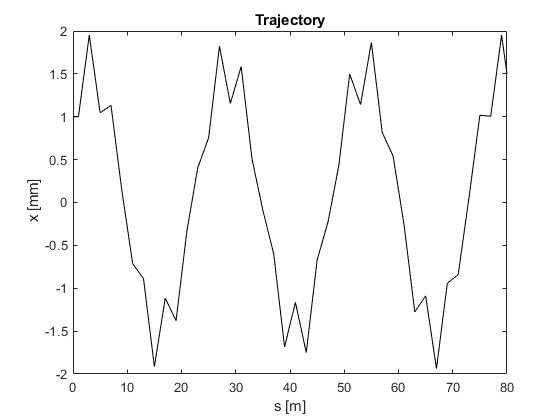

plot(spos,data,'k')
xlabel('s [m]'); ylabel('\beta [m]')

title('Beta function in one FODO cell')

We observe an oscillation with aminimum at the location of the defocusing quadrupole at s=1 m and a maximum in the focusing quadrupole at s=3 m.

## Betafunction through ten FODO cells

 Mapping the beta function through 10 FODO cells makes it necessary to increas the length of the` beamline` and update all transfer matrices

beamline=repmat(fodo,10,1);
[Racc,spos,nmat,nlines]=calcmat(beamline);

We do not need to re-calculate sigma0, because it is periodic and we can therefore use the one determined from a single cell. Let's propagate the beta function `sigma0` through the 10 FODO cells and plot the result

data=zeros(1,nmat);   % allocate memory
for k=1:nmat
  sigma=Racc(:,:,k)*sigma0*Racc(:,:,k)';
  data(k)=sigma(1,1);   % that's the beta
end

Qtune = 0.1580

alpha0 = 1.1372

beta0 = 4.2348

gamma0 = 0.5415

plot(spos,data,'k')
xlabel('s [m]'); ylabel('\beta [m]')
title('Beta function in ten FODO cells')

It's just ten copies of the beta function through a single cell.

## Adjust Qtune to 0.25

Let's go back to a single cell an adjust the quadrupoles such that the tune for one cell is Qtune=0.25. Which focal length approximatelydoes the job? Try to set the tune to 0.16666=1/6. What is F in that case?

3.356% adjust focal length F

sigma0 =     4.2348   -1.1372
   -1.1372    0.5415


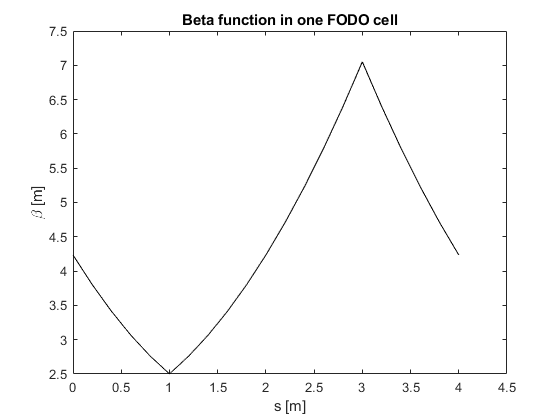

F=ans; % focal length of the quadrupoles
fodo=[ 1,  5,  0.2,  0;    
	     2,  1,  0.0, -F;    % QD
	     1, 10,  0.2,  0;    
	     2,  1,  0.0,  F;    % QF/2
       1,  5,  0.2,  0];   
beamline=fodo;
[Racc,spos,nmat,nlines]=calcmat(beamline);
Rend=Racc(:,:,end);    
[Qtune,alpha0,beta0,gamma0]=R2beta(Rend)

## Automatic tune adjustment

Now we use fminsearch() to set the tune to a desired value. To do so we need to define a cost function that I often call $\chi^2$ or chisq. Here we use the name `chisq_tune()`. It receives a guess for the focal length `F` and returns the difference betwen the tune value for that `F` and the desired tune, here 0.25. Such a function is defined in the appendix.

% global beamline   % needed to make it available inside chisq_tune()
F0=3;     % starting guess
[Fnew,fval]=fminsearch(@chisq_tune,F0)  
beamline  % just look at the new beamline description

Fnew is the new focal length that will give you the desired tune. let's verify that

[Racc,spos,nmat,nlines]=calcmat(beamline); 
Rend=Racc(:,:,end);    
Qtune=R2beta(Rend)

Now look at the function chisq_tune() in the appendix and change it such that Qtune becomes 1/6. What value for the focal length do you find? 

## Matching FODO cells with Qtune=0.1666 to those with Qtune=0.25

This is also called matching $60^o$ cell to a $90^o$ cell, because of  $60^o/360^0=0.1666$ and  $90^o/360^0=0.25$.

We found in the previous matching exercise that $F=\sqrt{2}$  gave Qtune=0.25 and  and $F=2$ gave Qtune=0.1666, which allows us to define the two cells in the following way

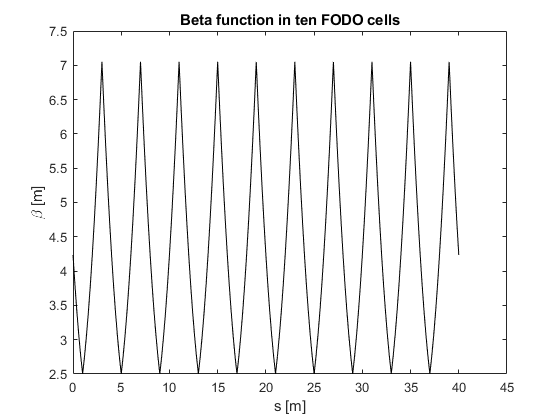

F=2; % focal length of the quadrupoles
fodo60=[ 1,  5,  0.2,  0;    
	     2,  1,  0.0, -F;    % QD
	     1, 10,  0.2,  0;    
	     2,  1,  0.0,  F;    % QF/2
       1,  5,  0.2,  0];   
F=sqrt(2);
fodo90=[ 1,  5,  0.2,  0;    

	     2,  1,  0.0, -F;    % QD
	     1, 10,  0.2,  0;    
	     2,  1,  0.0,  F;    % QF/2
       1,  5,  0.2,  0];  

Let's look at the beta function along that beamline. To do so we first calculate the periodic beam matrix for the $90^o$ cell

beamline=fodo60;

ans = 3.3560

[Racc,spos,nmat,nlines]=calcmat(beamline);
Rend=Racc(:,:,end);
[Qtune,alpha60,beta60,gamma60]=R2beta(Rend)
sigma60=[beta60,-alpha60;-alpha60,gamma60]

Now let's build a long beamline, starting with two fodo60, followed by six fodo90 cells and display the betafunction along this beam line, if we start with the input beam sigma60

beamline=[fodo60;fodo60;repmat(fodo90,6,1)];
[Racc,spos,nmat,nlines]=calcmat(beamline);
data=zeros(1,nmat);   % allocate memory
for k=1:nmat
  sigma=Racc(:,:,k)*sigma60*Racc(:,:,k)';
  data(k)=sigma(1,1); 

Qtune = 0.0963

alpha0 = 1.0476

beta0 = 6.7193

gamma0 = 0.3122

end
plot(spos,data,'k'); xlabel('s [m]'); ylabel('\beta [m]')
title('Unmatched fodo60 to fodo90 transition')

We observe that the beam that is matched for the fodo60 cell does not show a regular pattern once it enters the fodo90 cells. We therefore try to adjust the two quadrupoles in the second fodo60 cell to try to minimize the irregularity. Note that these two quads are now in line 7 and 9, respectively. The second cell we refer to as the *matching cell.*

beamline(7,4)=-2.044;
beamline(9,4)=2.0934;
[Racc,spos,nmat,nlines]=calcmat(beamline);

Fnew = 1.4142

fval = 1.9933e-11

data=zeros(1,nmat);   % allocate memory

beamline =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -1.4142
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    1.4142
    1.0000    5.0000    0.2000         0


for k=1:nmat
  sigma=Racc(:,:,k)*sigma60*Racc(:,:,k)';
  data(k)=sigma(1,1); 
end

Qtune = 0.2500

plot(spos,data,'k'); xlabel('s [m]'); ylabel('\beta [m]'); ylim([0,10])
title('Matching by hand')

Did you manage to get a smooth and periodic beta function through the downstream part of the beamline? If not, try out the following code, which uses `fminsearch()` to adjust the two quads such that $\alpha$ and $\beta$ at the start become those of the downstream $90^o$ cells at the start of the third cell a s=8 m, which is the first $90^o$ cell.

## Automatic matching

Let us first find out what $\alpha$ and $\beta$ at the start of the  $90^o$ cells is

beamline=fodo90;
[Racc,spos,nmat,nlines]=calcmat(beamline);
Rend=Racc(:,:,end);
[Qtune,alpha90,beta90,gamma90]=R2beta(Rend)

We find that $\beta=3$m and $\alpha=\sqrt{2}$.  Now we need to define a `chisq_beta()` function that takes the two focal lengths for the two quadrupoles as input and returns the squared difference between the calculated beta function at  the end of the matching cell and those of the downstrem $90^o$ cells. Let's base the matching cell on the $90^o$ cell

sigma0=sigma60;           % use sigma60 as starting matrix "global sigma0"
beamline=fodo90;
F0=[-2,2];    % initial guesses
[F,fval]=fminsearch(@chisq_beta,F0)
matching=beamline;    % save the resulting beamline as matching cell

And now we can reassemble the beamline consisting of one fodo60 cell, a matching cell, and four fodo90 cells, calculate the transfer matrices and plot the beta functions.

beamline=[fodo60;matching;repmat(fodo90,4,1)];
[Racc,spos,nmat,nlines]=calcmat(beamline);
data=zeros(1,nmat);   % allocate memory
for k=1:nmat
  sigma=Racc(:,:,k)*sigma60*Racc(:,:,k)';
  data(k)=sigma(1,1); 
end
plot(spos,data,'k'); xlabel('s [m]'); ylabel('\beta [m]'); ylim([0,10])
title('After automatic matching')

And that concludes this quick tutorial. Please do also have a look at the service functions in the Appendix below. They generate the transfer matrices, translate a transfer matrix to Twiss parameters, and calculate the chisq for the automatic matching of the tune and the beta function, respectively.

## Appendix

### Transfer matrix for a drift space `D(L)`

The function `D(L) ` receives the length` L `of a drift space and resturns the 2x2 transfer matrix` out` for a drift space.

function out=D(L)
  out=[1,L;0,1];

Qtune = 0.1667

alpha60 = 1.1547

beta60 = 4.0415

gamma60 = 0.5774

end

sigma60 =     4.0415   -1.1547
   -1.1547    0.5774


### Transfer matrix for a thin-lens quadrupole `Q(F)`

The function `Q(F)` receives the  focal length` F `as input and returns the 2x2 transfer matrix` out` for a thin-lens quadrupole.

function out=Q(F)
out=eye(2);
if abs(F)<1e-8, return; end   % turn off, if F=0
out=[1,0;-1/F,1];             % transfer matrix
end

### The function `calcmat()` to calculate all transfer matrices

The following function receives the `beamline` description as input and returns

- Racc(2,2,nmat): transfer matrices from the start to the each of each segment, such that R(:,:,end) is the transfer matrix from the start to the end of the beamline.

- spos: position along the beamline after each segment, useful when plotting.

- nmat: number of segments 

- nlines: number of lines in the beamline 

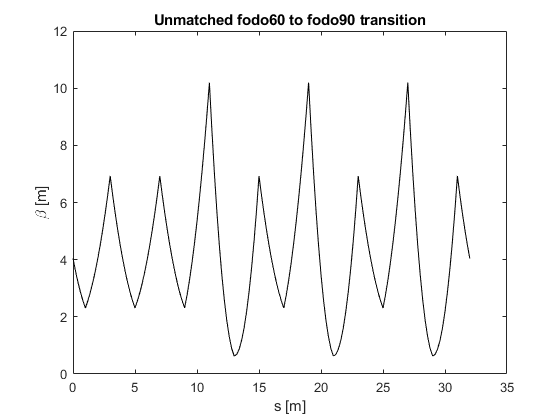

% calcmat.m, calculate the transfer-matrices
function [Racc,spos,nmat,nlines]=calcmat(beamline)
ndim=size(D(1),1); 
nlines=size(beamline,1);      % number of lines in beamline
nmat=sum(beamline(:,2))+1;    % sum over repeat-count in column 2

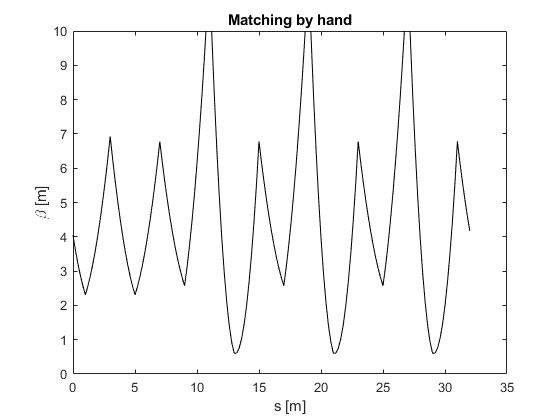

Racc=zeros(ndim,ndim,nmat);   % matrices from start to element-end
Racc(:,:,1)=eye(ndim);        % initialize first with unit matrix
spos=zeros(nmat,1);           % longitudinal position
ic=1;                         % element counter
for line=1:nlines             % loop over input elements
  for seg=1:beamline(line,2)  % loop over repeat-count 
     ic=ic+1;               % next element          
     Rcurr=eye(2);          % matrix in next element
     switch beamline(line,1)  
       case 1   % drift
         Rcurr=D(beamline(line,3));
       case 2    % thin quadrupole

         Rcurr=Q(beamline(line,4)); 
       otherwise
         disp('unsupported code')
     end		  
     Racc(:,:,ic)=Rcurr*Racc(:,:,ic-1);    % concatenate 
     spos(ic)=spos(ic-1)+beamline(line,3); % position of element   
  end
end

Qtune = 0.2500

alpha90 = 1.4142

beta90 = 3

gamma90 = 1.0000

end

### R2beta()

The function R2beta() receives a transfer matrix `R` as input and returns the "tune" $Q=\mu/2\pi$ for the transfer matrix R, as well as the periodic Twiss parameters $\alpha$, $\beta$, and $\gamma$.

function [Q,alpha,beta,gamma]=R2beta(R)
mu=acos(0.5*(R(1,1)+R(2,2)));
if (R(1,2)<0), mu=2*pi-mu; end
Q=mu/(2*pi);

F =    -2.0294    1.6602


fval = 2.3561e-09

beta=R(1,2)/sin(mu);
alpha=(0.5*(R(1,1)-R(2,2)))/sin(mu);
gamma=(1+alpha^2)/beta;
end

### chisq_tune()

This function receives a guess for the focal length F and calculates the squared difference between the desired tune and tune for this F. 

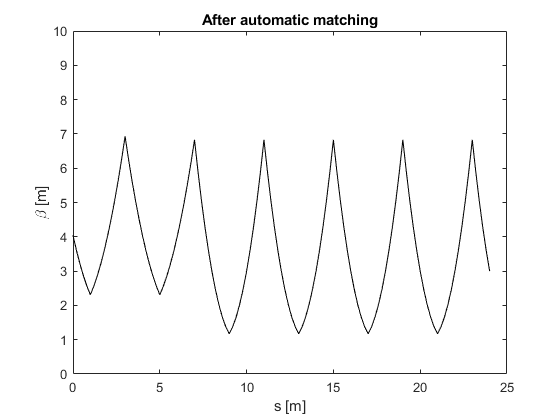

function chisq=chisq_tune(F)
global beamline sigma0
beamline(2,4)=-F;     % set the two quadrupoles, here QD
beamline(4,4)=F;      % and here QF
[Racc,spos,nmat,nlines]=calcmat(beamline);  % update transfer matrices
Rend=Racc(:,:,end);                         % the last one
[Qtune,alpha0,beta0,gamma0]=R2beta(Rend);   % get Qtune

chisq=(Qtune-0.25)^2;                       % difference to minimize
end

### chisq_beta()

This function receives the focal lengths of the two quads in the matching cell and returns the aquared difference between $\alpha$ and $\beta$ for the $90^o$ cell and the one derived from the provided quad values

function chisq=chisq_beta(F)
global beamline sigma0
beamline(2,4)=F(1);      % set the two quadrupoles, here QD
beamline(4,4)=F(2);      % and here QF
[Racc,spos,nmat,nlines]=calcmat(beamline);  % update transfer matrices
Rend=Racc(:,:,end);   
sigma=Rend*sigma0*Rend';
beta=sigma(1,1); alpha=-sigma(1,2);
beta90=3; alpha90=sqrt(2);
chisq=(beta-beta90)^2+(alpha-alpha90)^2;
end